# Problem Set 2

## Problem 1

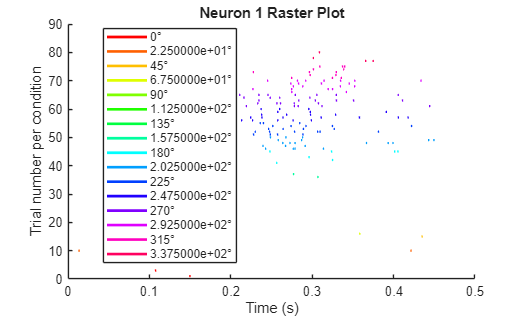

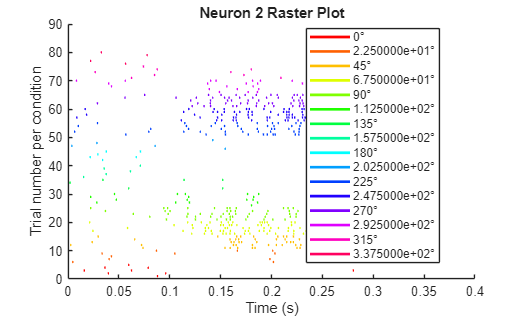

% Part A
neurons = length(Data.spikes);
mean_spikes = cell(1, neurons);

for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    for cond = 1:length(unique_conds)
        cond_mask = stimuli == unique_conds(cond);
        spikes_per_cond = spikes(cond_mask);
        counts = cellfun(@length, spikes_per_cond);
        mean_spikes{neuron}(cond) = mean(counts);
    end
end

% Part B
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    figure; hold on;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    colors = hsv(length(unique_conds)); 
    row = 1;
    
    for cond = 1:length(unique_conds)
        dir = unique_conds(cond);
        trial_idx = find(stimuli == dir);
        legend_handles(cond) = plot(nan, nan, 'Color', colors(cond,:), 'LineWidth', 2);
        for t = 1:length(trial_idx)
            trial_spikes = spikes{trial_idx(t)};
            for s = 1:length(trial_spikes)
                plot([trial_spikes(s) trial_spikes(s)], [row-0.4 row+0.4], 'Color', colors(cond,:), 'LineWidth', 1);
            end
            row = row + 1;
        end
    end
    xlabel('Time (s)');
    ylabel('Trial number per condition');
    title(['Neuron ' num2str(neuron) ' Raster Plot']);
    
    legend_labels = arrayfun(@(cond) sprintf('%d°', cond), unique_conds, 'UniformOutput', false);
    legend(legend_handles, legend_labels, 'Location', 'best');
end

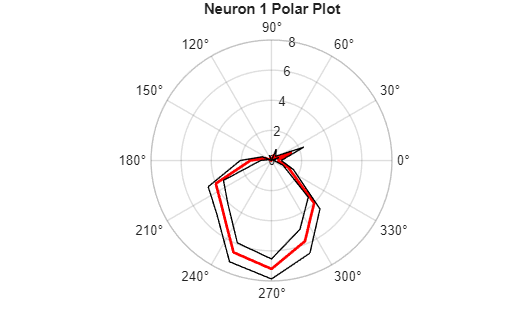

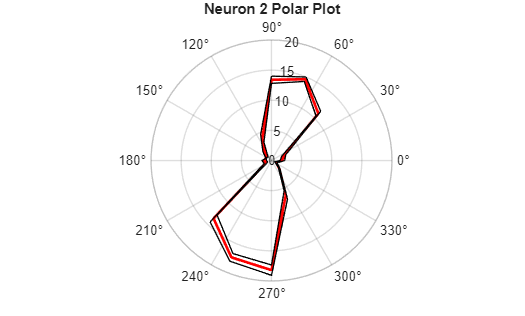


% Part C
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    
    mean_rates = zeros(size(unique_conds));
    sem_rates = zeros(size(unique_conds));
    
    for cond = 1:length(unique_conds)
        dir = unique_conds(cond);
        trial_idx = find(stimuli == dir);
        spike_counts = cellfun(@length, spikes(trial_idx));
        mean_rates(cond) = mean(spike_counts);
        sem_rates(cond) = std(spike_counts) / sqrt(length(spike_counts));
    end
    
    theta = deg2rad(unique_conds);
    theta_closed = [theta; theta(1)];
    mean_closed = [mean_rates; mean_rates(1)];
    sem_closed = [sem_rates; sem_rates(1)];

    upper = mean_rates + sem_rates;
    lower = mean_rates - sem_rates;
    upper_closed = [upper; upper(1)];
    lower_closed = [lower; lower(1)];
    
    figure;
    polarplot(theta_closed, mean_closed, 'r-', 'LineWidth', 2);
    hold on;
    polarplot(theta_closed, upper_closed, 'k-', 'LineWidth', 1);
    polarplot(theta_closed, lower_closed, 'k-', 'LineWidth', 1);
    
    title(['Neuron ' num2str(neuron) ' Polar Plot']);
end

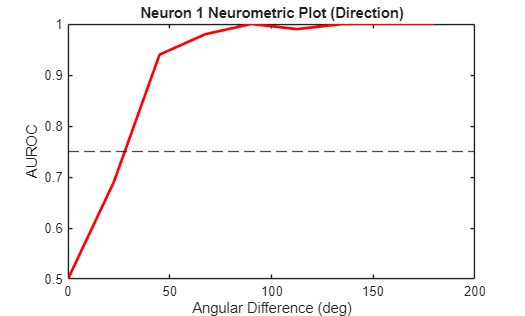

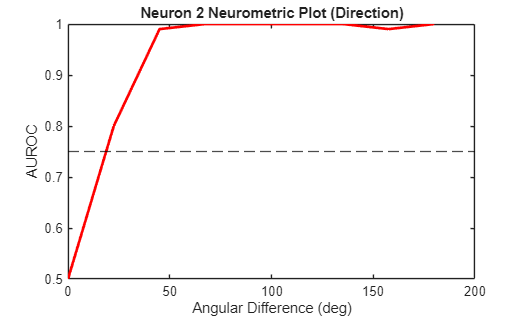


% Part D
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    
    mean_rates = zeros(size(unique_conds));
    
    for cond = 1:length(unique_conds)
        idx = stimuli == unique_conds(cond);
        mean_rates(cond) = mean(cellfun(@length, spikes(idx)));
    end
    
    [~, pref_idx] = max(mean_rates);
    pref_dir = unique_conds(pref_idx);
    
    auroc_vals = [];
    angle_diffs = [];
    
    pref_counts = cellfun(@length, spikes(stimuli == pref_dir));
    
    for cond = 1:length(unique_conds)
        
        test_dir = unique_conds(cond);
        test_counts = cellfun(@length, spikes(stimuli == test_dir));
        
        labels = [ones(length(pref_counts),1); zeros(length(test_counts),1)];
        scores = [pref_counts; test_counts];
        
        [~,~,~,AUC] = perfcurve(labels, scores, 1);
        
        diff = abs(pref_dir - test_dir);
        diff = min(diff, 360 - diff);
        
        auroc_vals(end+1) = AUC;
        angle_diffs(end+1) = diff;
    end

    [unique_diffs, ~, idx_groups] = unique(angle_diffs);
    mean_auroc = accumarray(idx_groups, auroc_vals, [], @mean);

    [unique_diffs, sort_idx] = sort(unique_diffs);
    mean_auroc = mean_auroc(sort_idx);

    figure;
    plot(unique_diffs, mean_auroc, 'r-', 'LineWidth', 2);
    hold on;
    yline(0.75, 'k--', 'LineWidth', 1);
    
    xlabel('Angular Difference (deg)');
    ylabel('AUROC');
    title(['Neuron ' num2str(neuron) ' Neurometric Plot (Direction)']);   
    ylim([0.5 1]);
end

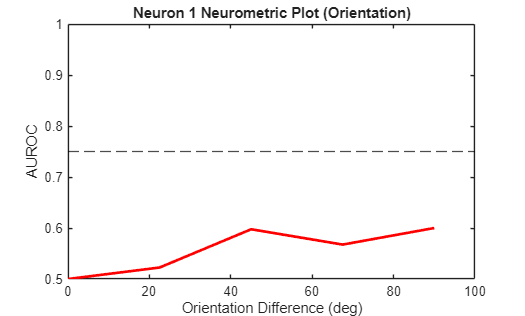

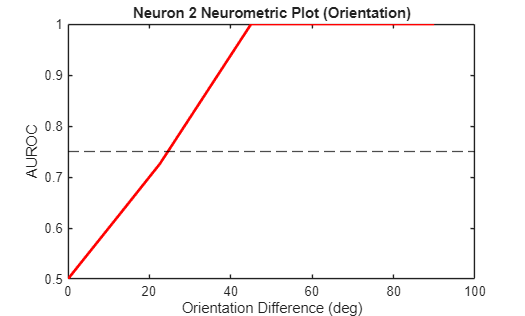


% Part E
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    directions = Data.stimuli{1, neuron}(trial_mask, 3);
    
    orientations = mod(directions + 90, 180);
    unique_conds = unique(orientations);
    mean_rates = zeros(size(unique_conds));
    
    for cond = 1:length(unique_conds)
        idx = orientations == unique_conds(cond);
        mean_rates(cond) = mean(cellfun(@length, spikes(idx)));
    end
    
    [~, pref_idx] = max(mean_rates);
    pref_ori = unique_conds(pref_idx);
    
    pref_counts = cellfun(@length, spikes(orientations == pref_ori));
    
    auroc_vals = [];
    ori_diffs = [];
    
    for cond = 1:length(unique_conds)
        
        test_ori = unique_conds(cond);
        test_counts = cellfun(@length, spikes(orientations == test_ori));
        
        labels = [ones(length(pref_counts),1); zeros(length(test_counts),1)];
        scores = [pref_counts; test_counts];
        
        [~,~,~,AUC] = perfcurve(labels, scores, 1);
        
        diff = abs(pref_ori - test_ori);
        diff = min(diff, 180 - diff);
        
        auroc_vals(end+1) = AUC;
        ori_diffs(end+1) = diff;
    end
    [unique_diffs, ~, idx_groups] = unique(ori_diffs);
    mean_auroc = accumarray(idx_groups, auroc_vals, [], @mean);

    [unique_diffs, sort_idx] = sort(unique_diffs);
    mean_auroc = mean_auroc(sort_idx);
    
    figure;
    plot(unique_diffs, mean_auroc, 'r-', 'LineWidth', 2);
    hold on;
    yline(0.75, 'k--', 'LineWidth', 1);
    
    xlabel('Orientation Difference (deg)');
    ylabel('AUROC');
    title(['Neuron ' num2str(neuron) ' Neurometric Plot (Orientation)']);
    ylim([0.5 1]);

end